Ligning at kunne

U er overall heat transfer coefficient.

3.28

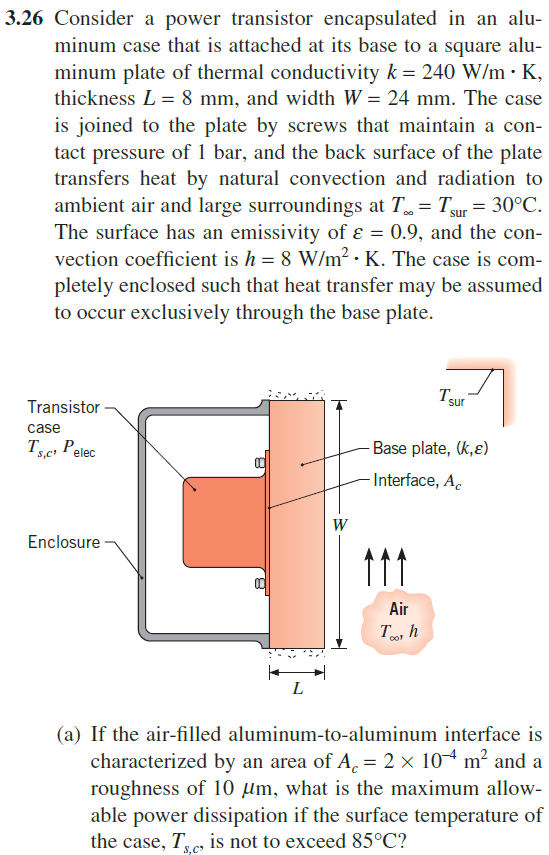

clear all

k = 240; % W/(m*K)
L = 0.008; %m %længde
W = 0.024;%m
T_inf = 30+273.15; % K
T_sur = T_inf;
epsilon = 0.9;
h = 8; % W/(M^2 * K) 
A_plate = W^2; % Area of square plate
A_c =2e-4;
mu = 10e-6;
T_sc = 85 + 273.15; %K
sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
R_tc = 2.75e-4; %m^2 * K/ W % Thermal Resistance fra Table 3.1 side 106 (husk det er 10^-4)

 * A

 * A

Det antages at varmen spredes instantat til hele højden af pladen og derefter går igennem pladen.

Da vi har steady state er q ens igennem alle modstande.

steady state dT/dt = 0 

(1) Steady-state, 

(2) Negligible heat transfer from the enclosure, to the surroundings. 

(3) One-dimensional conduction in the base plate, 

(4) Radiation exchange at surface of base plate is with large surroundings, (5) Constant thermal conductivity.

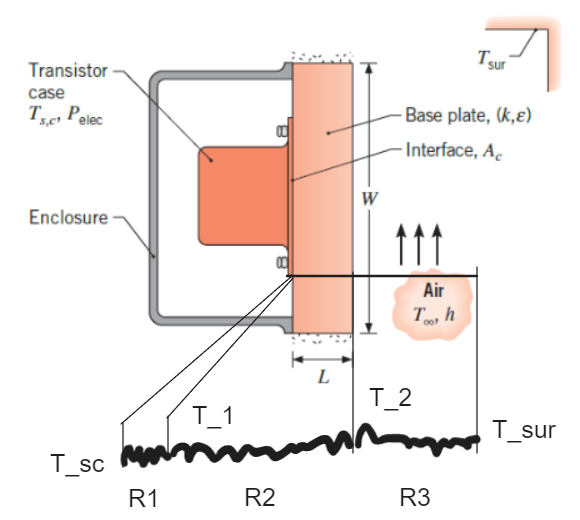

syms T_1 T_2 q T_var
T_2 = sym("T_2", "real");
T_2 = sym("T_2", "positive");

h_r = epsilon * sigma * (T_2 +T_sur) * (T_2^2 +T_sur^2); %ligning 1.9

% q_saml = (T_sc - T_1)/R_tc
% q_cond = -k*A_plate/L * (T_1 - T_2)

R1 = R_tc/A_c %modstanden af plade samlingen

R1 = 1.3750

R2 = L/(k *A_plate) %modstanden igennem pladen

R2 = 0.0579

Vi samler de to ligninger således vi eliminere $T_1$

q_smal_cond_eq = (T_sc - T_2)/ (R1 + R2);

q_conv = h * A_plate * (T_2 - T_inf);
q_rad = epsilon * sigma * (T_2^4 - T_sur^4) * A_plate; % = h_r * A_plate * (T_2 - T_sur) % 

R3 er paralel forbindelse imellem R3_conv og R3_rad

R3_conv = 1/(h*A_plate);
R3_rad = 1/(h_r*A_plate);
R3 = 1/(1/R3_conv + 1/R3_rad);

q_conv_rad_eq  = q_conv + q_rad % = (T_2 - T_inf)/ R3

$$q\_conv\_rad\_eq = \frac{69407503175365443\,{T_{2}}^{4}}{2361183241434822606848000000}+\frac{72\,T_{2}}{15625}-\frac{20366284418783428455829683106813593}{12379400392853802748991242240000000}$$

Vi sætter de to fundne ligninger lig med hinanden

T_2_sol = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
T_2_sol_ = vpa(T_2_sol, 5)% - 273.75

$$T\_2\_sol\_ = 357.46$$


q = (T_sc - T_sur)/(R1 + R2 + subs(R3, T_2, T_2_sol));

P_elec = vpa(q,5)

$$P\_elec = 0.48193$$

h_lin = linspace(4,200, 200-3);
T_2_sol = [];
qs = [];

for i = 1:length(h_lin)
    q_conv = h_lin(i) * A_plate * (T_2 - T_inf);
    q_conv_rad_eq  = q_conv + q_rad; % = (T_2 - T_inf)/ R3

    T_2_sol(i) = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
    % vpa(T_2_sol, 5)% - 273.75
    
    qs(i) = (T_sc - T_sur)/(R1 + subs(R2, h, h_lin(i)) + subs(R3, T_2, T_2_sol(i)));
end

sanity_check_q = qs(5)

sanity_check_q = 0.4819

sanity_check_h_lin = h_lin(5)

sanity_check_h_lin = 8

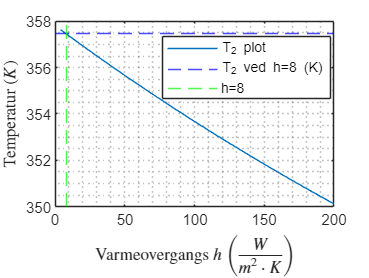


plot(h_lin, T_2_sol, 'DisplayName','T_2 plot')
grid('minor')
% yline(T_sc, 'b--', 'DisplayName','T_sc (K)')
yline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
xline(h,'g--', 'DisplayName','h=8')
xlabel("Varmeovergangs $h$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
ylabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')

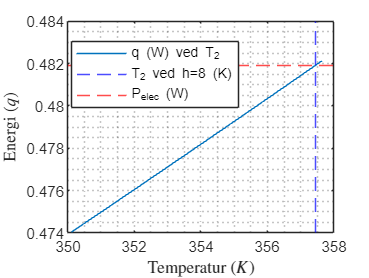



plot(T_2_sol, qs, 'DisplayName','q (W) ved T_2')
grid('minor')
xline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
yline(double(P_elec), 'r--', 'DisplayName','P_elec (W)')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')

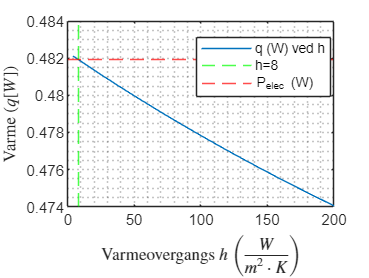



plot(h_lin, qs, 'DisplayName','q (W) ved h')
grid('minor')
xline(h,'g--', 'DisplayName','h=8')
yline(double(P_elec), 'r--', 'r--', 'DisplayName','P_elec (W)')
ylabel("Varme $(q [W])$", Interpreter="latex")
xlabel("Varmeovergangs $h$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
legend('Location','best')

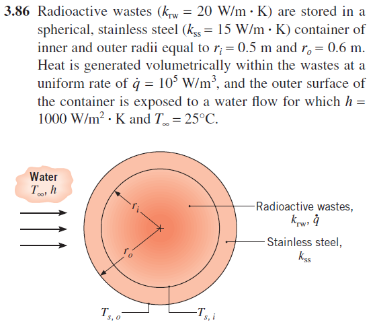

clear all
clf
k_rw = 20; % W/m*K
k_ss = 15; % W/m*K
r_i = 0.5; %m
r_o = 0.6; % m
q_dot = 1e5; % W/m^3
h = 1000; % W/m^2*K
T_inf = 25 + 273.15; % K

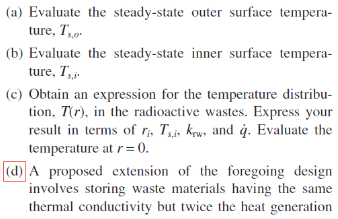

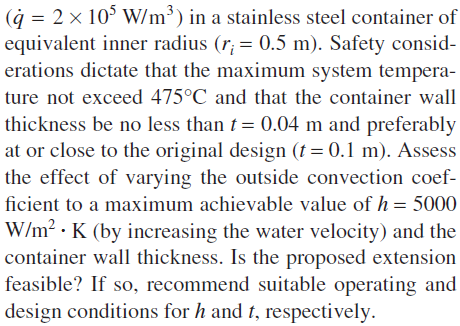

(a)

Bruger Gauss's law  eqvivalent


$$q(r) = \int \dot q\ dV = \dot q  \frac{4}{3} \pi r^3$$


Vi finder T_s,o ved at gå igennem film laget hvor den totale varme der kommer ud er q genneret af kernen

syms T_so T_si
assume(T_so, 'real')

q = q_dot * 4/3 * pi * r_i^3;
A_o = 4*pi*r_o^2;
q_conv = h*A_o *(T_so - T_inf);

T_so_ = solve(q == q_conv, T_so);
T_so = double(vpa(T_so_, 6))

T_so = 309.7241

T_so_C = T_so - 273.15

T_so_C = 36.5741

(b)

R_cond =

q = 

q_cond = (T_si - T_so) * 4 * pi * k_ss /(1/r_i - 1/r_o)

$$q\_cond = 45\,\pi \,\left(4\,T_{\mathrm{si}}-\frac{42568152605825}{34359738368}\right)$$


T_si_ = solve(q == q_cond, T_si);
T_si = double(vpa(T_si_, 6))

T_si = 402.3167

T_si_C = T_si - 273.15

T_si_C = 129.1667

(c)

syms T(r) r T_rw

q_cond_rw = (T_rw - T_si) * 4 * pi * k_rw /(1/r_i - 1/r) %wrong

$$q\_cond\_rw = -\frac{20\,\pi \,\left(4\,T_{\mathrm{rw}}-\frac{24139}{15}\right)}{\frac{1}{r}-2}$$

q_rw = -q_dot * 4/3 * pi * r^3; %wrong


T(r) = solve(q_cond_rw == q_rw, T_rw); %wrong
vpa(T(1),5)

$$ans = -1264.4$$

% vpa(T(0.1), 5) - 273.15


rs = linspace(0.00001, 0.499999);
double(T(rs))

ans =   402.3167  402.3589  402.4836  402.6882  402.9700  403.3265  403.7552  404.2535  404.8187  405.4483  406.1398  406.8905  407.6979  408.5594  409.4724  410.4343  411.4427  412.4948  413.5882  414.7201  415.8882  417.0897  418.3222  419.5830  420.8695  422.1793  423.5096  424.8580  426.2218  427.5985  428.9855  430.3803  431.7802  433.1826  434.5851  435.9850  437.3797  438.7667  440.1433  441.5071  442.8555  444.1858  445.4955  446.7819  448.0427  449.2750  450.4765  451.6445  452.7764  453.8696


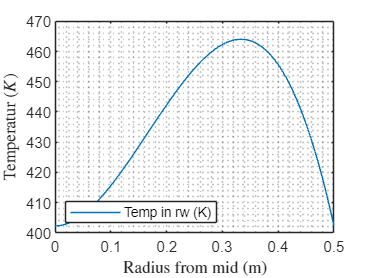

plot(rs, double(T(rs)), 'DisplayName','Temp in rw (K)')
grid('minor')
ylabel("Temperatur $(K)$", Interpreter="latex")
xlabel("Radius from mid (m)", Interpreter="latex")
% help legend
legend('Location','southwest')

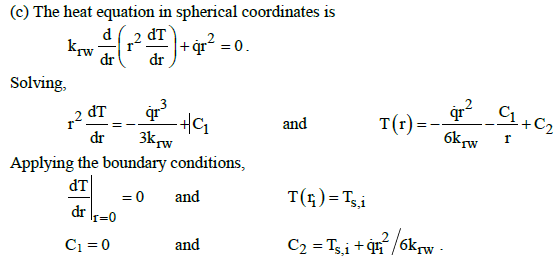

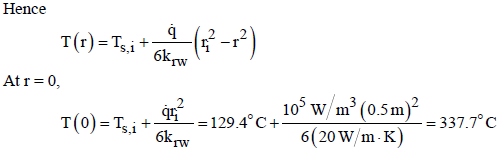

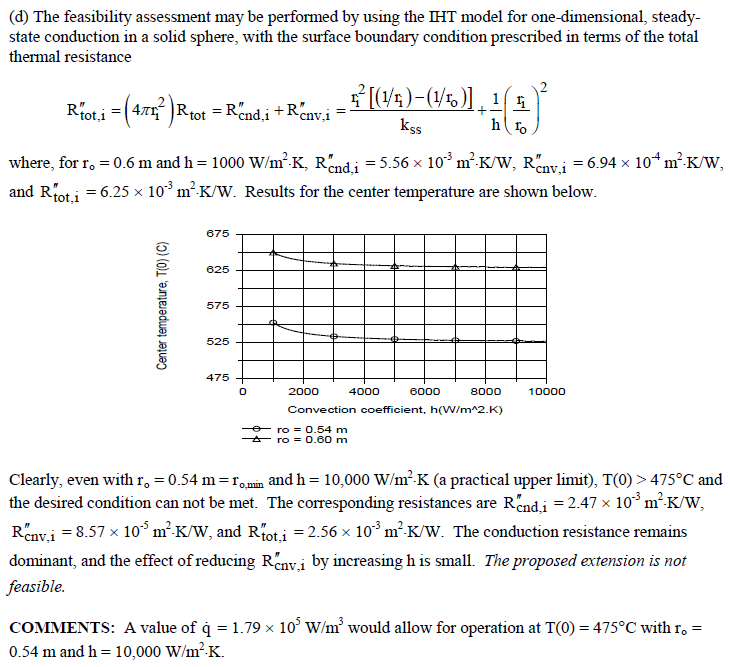

**3.102**

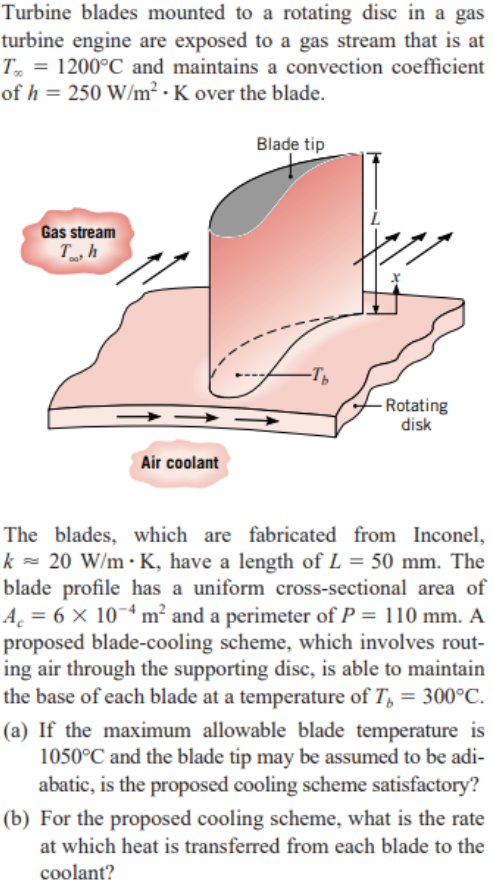

(1) One-dimensional, steady-state conduction in blade, 

(2) Constant k, 

(3) Adiabatic blade tip, 

(4) Negligible radiation.

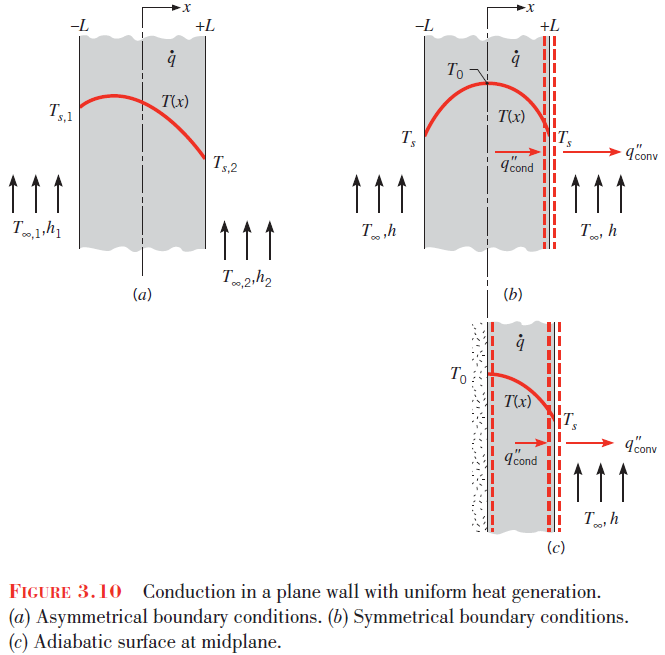

clear all
clf
k = 20; %W/m K
L = 0.050; %m
Ac = 6e-4; %m^2
P = 0.110; %m
h = 250; %W/m^2 K Gass stream
Tinf = 1200 + 273.15; % K  Gass stream
Tb = 300 + 273.15; % K
Tmax = 1050 + 273.15; % K

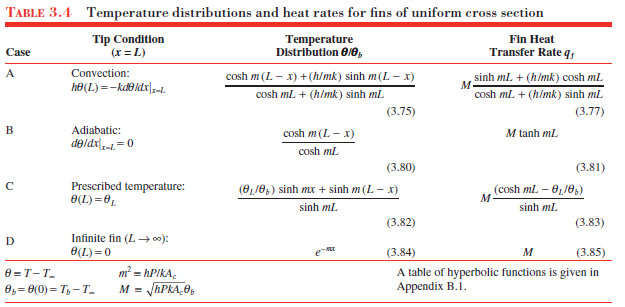

$\theta_L = T-T_{\infty}$  (temperatur forskellen fra enden af finnen(L) til der hvor luft strømmen er upåvirkede af overfladen)

h er konvections varmetallet

P er perimeter (omkredsen af finden i tværsnittet)

k er thermal conductivity, W/m ⋅ K

Ac er tværsnits arealet (for at bruge tabel 3.4)

**a)**

% q = Ac*h*(Tinf - Tmax)

format long g
syms T_sym
x = linspace(0,L,100);%L;
m = sqrt(h * P / (k*Ac))

m =           47.8713553878169


Vi finder varmen ud igennem finnnen

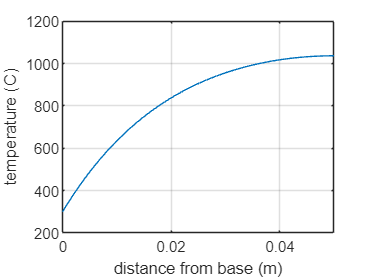

for i = 1:length(x)
    T_eq = (T_sym - Tinf)/(Tb - Tinf) == cosh( m*(L - x(i)) ) / cosh(m*L);
    T(i) = vpa(solve(T_eq, T_sym)  - 273.15 , 10);
end
T = double(T);
plot(x, T)
ylabel('temperature (C)')
xlabel('distance from base (m)')
grid('on')


T_tip = max(T)

T_tip =           1037.01267658474


Tmax

Tmax =                    1323.15


**b)**

theta_b = Tb - Tinf;
M = sqrt(h*P*k*Ac)*theta_b

M =          -517.010638188423


qf = M * tanh(m*L)

qf =          -508.461988445505


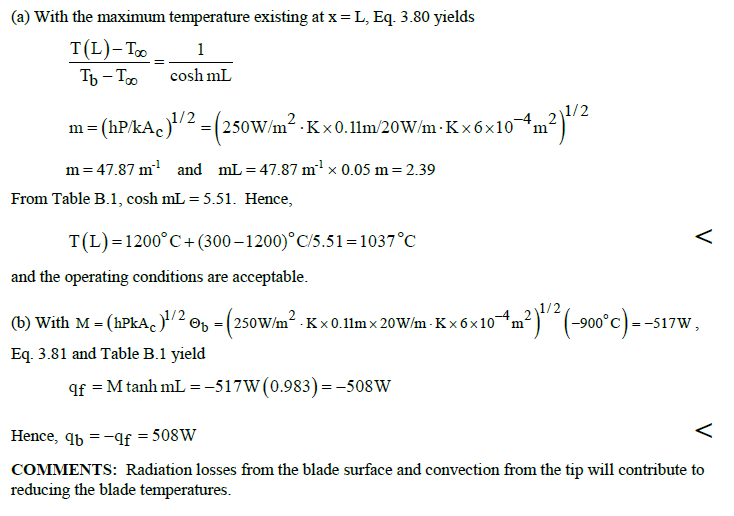

**3.144 (Mangler rigtig version)**

## Eksempler

eksempel 3.4

## Figurer og tabeller

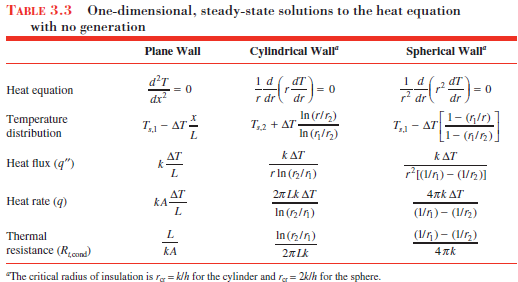

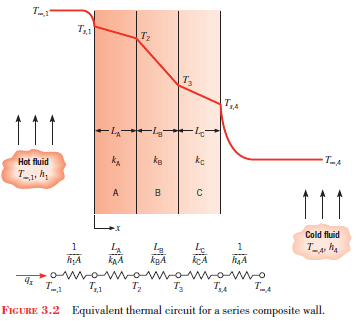

3.22 og sammenhængen til de grå formler 3.103, 3.107, 3.108, 3.109 og 3.110a